# Optic disk location

## 0. Prepare environment and Load image  

close all;clc;clearvars;
% I = imread('mergedCrop.jpg');
image = 'B09B_OD.tif.tif';

image = 'B09B_OD.tif.tif'

I = imread(['..\data\raw\02_FUNDUS_MJFF_baseline_ONH_NOMETADATA\' image]);

I = 768×768×3 uint8 array
I(:,:,1) =

    68    71    71    70    68    69    70    72    71    71    71    74    73    72    74    73    77    79    80    80    81    78    79    79    80    79    74    76    79    82    78    82    85    83    86    85    81    82    82    80    87    86    84    86    87    85    86    85    87    89    90    88    88    90    89    85    80    76    78    78    78    84    90    93    94    89    92    98    98    96    98    98    96    93    99    99    97    98    96    98    96    95    97    99    99    97    94    94    98    94    93    97    96    94    93    98   102   103   103   103   104   105   104   104   101   103    97    97    93    92    89    82    77    72    66    63    61    60    59    59    61    63    67    70    68    67    66    65    62    64    67    70    80    88    95   101   102    99   100   101   103   102    96    95    98    94    94    97    97    97    97    96    99    99    98   100   101    98    99    98  

## 1. Intensity homogeneization

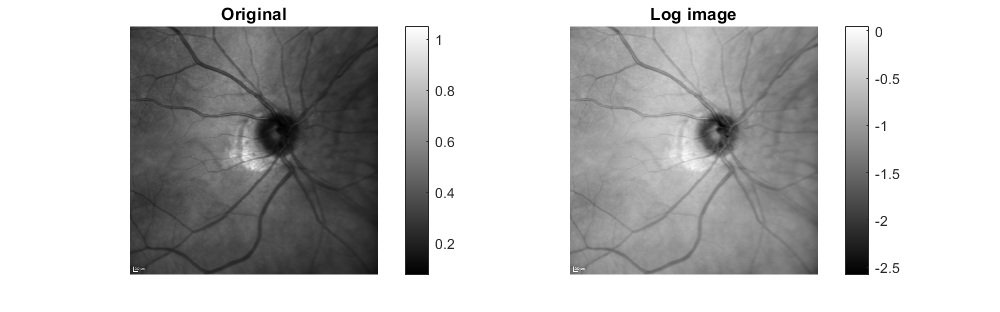

f = figure;
% RGB 2 gray and double
I = im2double(rgb2gray(I));
I = imresize(I,[500 500]);
subplot(121);imagesc(I);daspect([1 1 1]);axis off;title('Original');colorbar;
% Compute logarithm
I = log(I);
subplot(122); imagesc(I);title('Log image');daspect([1 1 1]);axis off;colorbar;
set(f,'position',[0 0 800 250]);colormap(gray);

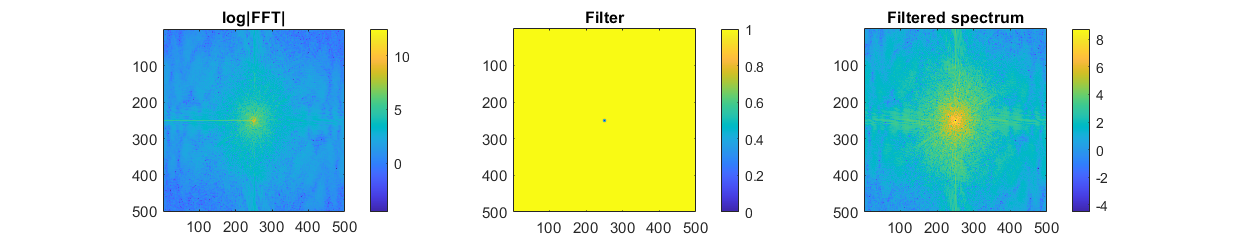


f = figure;
% Compute FFT
If = fftshift(fft2(I));
subplot(131);imagesc(log(abs(If)));colorbar;title('log|FFT|');daspect([1 1 1]);
% Define high-pass filter
sigma =5;nPoint = 500;
[u,v] = meshgrid(linspace(-500,500,nPoint),linspace(-500,500,nPoint));
G = 1/sqrt(2*pi*sigma).*exp(-(u.^2+v.^2)./(2*sigma^2));
G  =1-G;
G = G-min(G(:));
G = G./max(G(:));
% G = ones(500);
subplot(132);imagesc(G);title('Filter');colorbar;daspect([1 1 1]);
% Filter image
If = If.*G;
subplot(133);imagesc(log(abs(If)));title('Filtered spectrum');colorbar;daspect([1 1 1]);

set(f,'position',[0 0 1000 200])

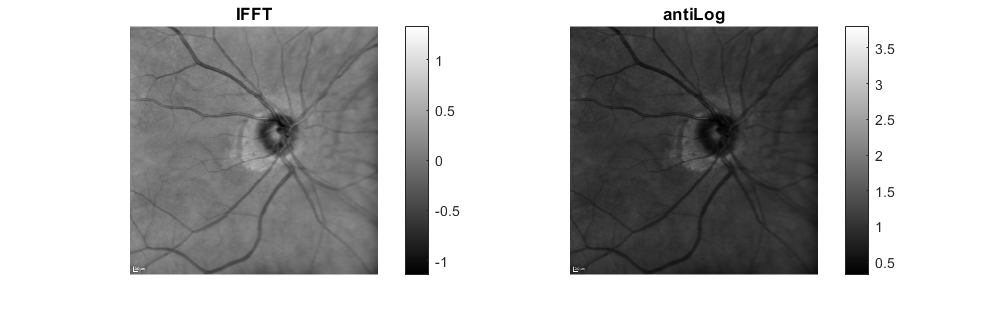

f = figure;
% IFFT
I = ifft2(ifftshift(If));
I = real(I);
subplot(121);imagesc(I);title('IFFT');daspect([1 1 1]); axis off;colorbar;
% caxis([prctile(I(:),1) prctile(I(:),99)]);
% Antilogarithm
I = exp(I);
subplot(122);imagesc(I);title('antiLog');daspect([1 1 1]);axis off;colorbar;
% caxis([prctile(I(:),1) prctile(I(:),99)]);
set(f,'position',[0 0 800 250]);colormap('gray')

## 2. Thresholding

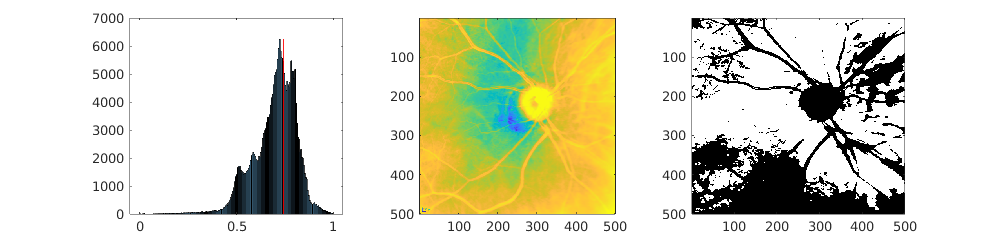

I = I -min(I(:)); I = I./max(I(:));

f = figure();
th = 62;
Ith = I < prctile(I,th);
subplot(131);h = histogram(I(:));hold on;plot([prctile(I(:),th) prctile(I(:),th)],[0 max(h.Values)],'r')
subplot(132);imagesc(I);daspect([1 1 1]);caxis([0 prctile(I(:),99)])
ax = subplot(133);imagesc(Ith);colormap(ax,"gray");
set(f,'position',[0 0 1000 240])

## 3.Finding connected components

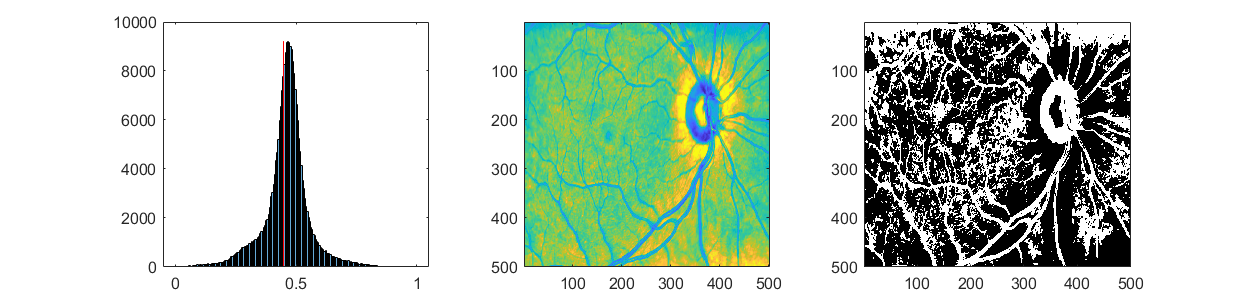

f = figure();
subplot(121);imagesc(I);colormap(ax,"gray");

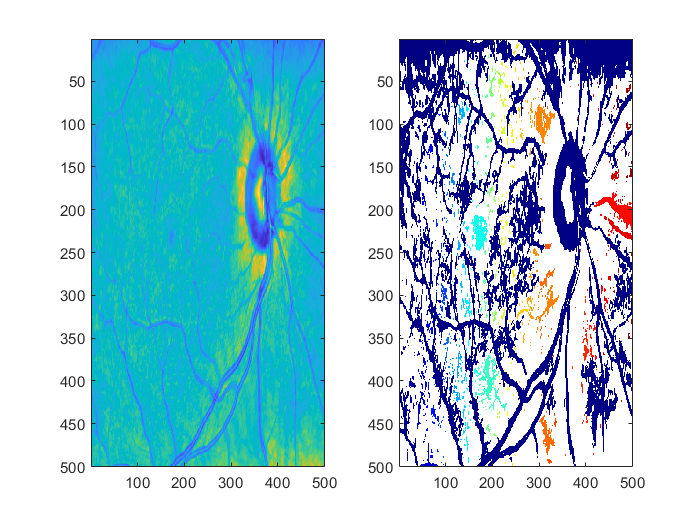

CC = bwconncomp(Ith);
L = bwlabel(Ith);
[group, nPix] = unique(L);
subplot(122);
imagesc(label2rgb(L));